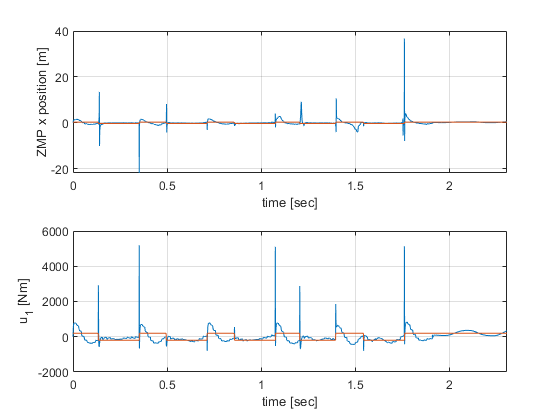

x_start = 0;
x_end = time(end);

figure
subplot(2,1,1)
plot(time, x_ZMP)
xlim([x_start,x_end])
hold on
plot(time, 0.3*flag(:,1))
xlabel('time [sec]')
ylabel('ZMP x position [m]')
hold off
grid on

subplot(2,1,2)
plot(time, inputTorque(:,1))
xlim([x_start,x_end])
hold on
plot(time, 200*flag(:,1))
hold off
xlabel('time [sec]')
ylabel('u_1 [Nm]')
grid on

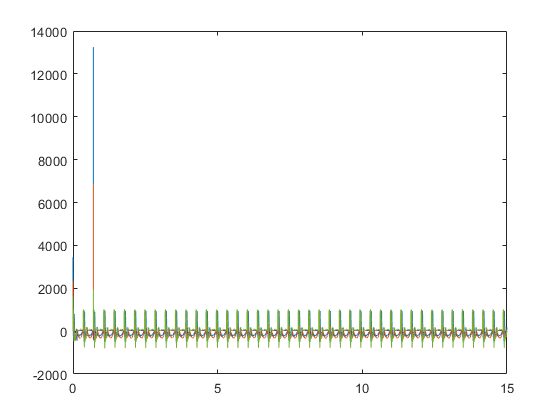

figure
plot(time, inputTorque)

% xlim([28,30])


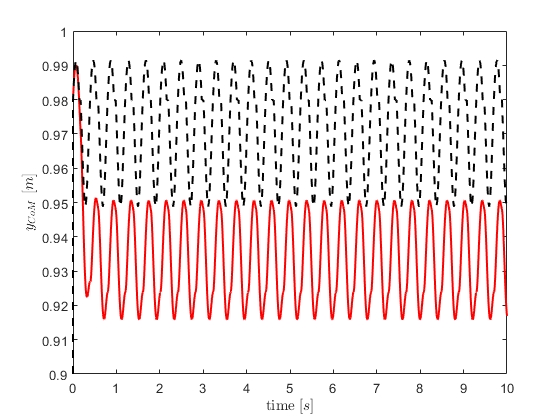

% y tracking error

figure
plot(time, CoM_acc(:,2), 'r', 'LineWidth', 1.5); hold on;
plot(time, des_z_dz_dx(:,2), 'k--', 'LineWidth', 1.5);
ylim([0.9,1.0]);
% xlim([28, 30]);
ylabel('$y_{CoM}$ $[m]$', 'Interpreter','Latex', 'FontWeight','bold');
xlabel('time $[s]$', 'Interpreter','Latex', 'FontWeight','bold');

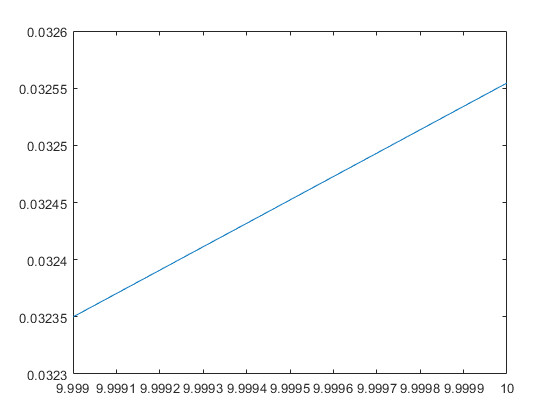


y_err = des_z_dz_dx(:,2) - CoM_acc(:,2);

figure
plot(time(10/sample_time:end), abs(y_err(10/sample_time:end)))

% xlim([28,30])

dx_avg = mean(CoM_acc(10/sample_time:end, 3))

dx_avg = 0.7275

dx_avg_slipsl = (dc.x_CoM(end) - dc.x_CoM(1))/dc.time(end)

Reference to non-existent field 'x_CoM'.

dx_err = abs(dx_avg_slipsl - dx_avg)


if time(end)>Tf -1
    theta_P(:,1) = rt_VLO(1,1,:); % atan2(dz_CoM, dx_CoM)
    z_P(:,1) = rt_VLO(1,2,:); % z_CoM position at VLO
    E_CoM(:,1) = rt_VLO(1,4,:); % energy of CoM at VLO
    %             VLOtimes = rt_VLO(1,5,:); % times when VLO happens
    
    vector_pc = [theta_P(2:end), z_P(2:end), E_CoM(2:end)] - [theta_P(1:end-1), z_P(1:end-1), E_CoM(1:end-1)]; % differences between consequent VLO points
    vector_pc = [vector_pc(:,1)/mean(theta_P), vector_pc(:,2)/mean(z_P), vector_pc(:,3)/mean(E_CoM)]; % normalizing these difference with average values
    vector_pc = abs(vector_pc);
    %             dist = sqrt(vector_pc(:,1).^2 + vector_pc(:,2).^2 + vector_pc(:,3).^2);
    
    VLO_diff = sum(sum([(vector_pc(1:end-1, :) + vector_pc(2:end, :))/2]));
    
    % another method to calculate
    mean_diff = sqrt(vector_pc(:,1).^2 + vector_pc(:,2).^2 + vector_pc(:,3).^2);
    trapz_VLO_diff = trapz(1:length(mean_diff), mean_diff);
%     clear theta_P z_P E_CoM vector_pc
end

figure
plot(vector_pc)

figure
plot(mean_diff)


i_start = 29330;
i_end = 29760;

CoM_start = calculate_com(simout(i_start,:), param, flag(i_start,2), [0,0,0,0,0])
CoM_end = calculate_com(simout(i_end,:), param, flag(i_end,2), [0,0,0,0,0])

avg_vel = (CoM_end(1) - CoM_start(1))/(time(i_end) - time(i_start))
avg_vel_SLIPSL = (dc.x_CoM(end) - dc.x_CoM(1))/(dc.time(end))

load('SLIPSL_Data\SLIPSLOpenOCL2020-12-02-14-47')

CoT_SLIPSL = calc_CoT_SLIPSL(sol)
% CoT_SLIPSL = 



